# Matching Features 

In this script, you'll work through two main examples. 

- In the first example you'll perform feature detection, extraction, and matching with the one way signs. Here, you'll explore each of the most useful name-value pair options and how they affect feature matching results with different goals in mind. 

- In the second example, you'll work with a pair of stop sign images. This time, you'll set all feature matching name-value pair options simultaneously and observe the results. 

- the last part we did a simple matching without any tuning with 3 algorithm Harris, SIFT, SURF to simply compare these 3.

**Important****: ***As you proceed through the script, run each section with the provided settings first. Then, try any specific alterations in the section-by-section instructions. Some of the intended examples will only work this way. Of course, after you've finished with the entire script, feel free to come back and change anything you want! *

## One Way Signs

The first step is to import and then examine the images you'll be working with. In general, don't forget to use the `im2gray` function to convert color images to grayscale before detecting and extracting features.

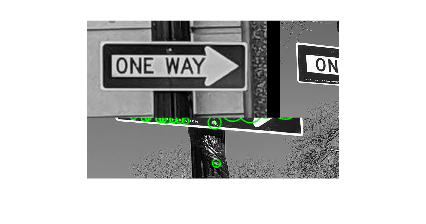

ow1 = imread("oneway1.png"); 
ow1 = im2gray(ow1);
ow2 = imread("oneway2.png"); 
ow2 = im2gray(ow2);
montage({ow1,ow2})

### Detecting SURF features

The next steps are detection, extraction, and matching. Here we detect SURF features. 

points1 = detectSURFFeatures(ow1);
points2 = detectSURFFeatures(ow2);

**Keeping strongest detections (optional) **

In this example, we chose to keep only the fifty strongest detections. This is not a generally required step, but sometimes you may want to focus on only the *strongest* feature detections to help match the *best* features. It also makes the detections much easier to see in this case, which is important since we will refer back to specific feature locations when we perform feature matching. 

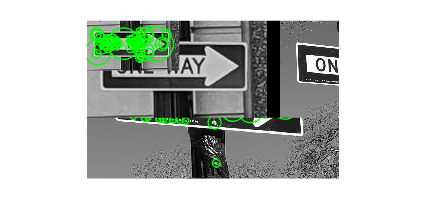

nKeep = 50; 
points1 = selectStrongest(points1,nKeep);
points2 = selectStrongest(points2,nKeep);

imshow(ow1)
hold on 
plot(points1)
hold off 

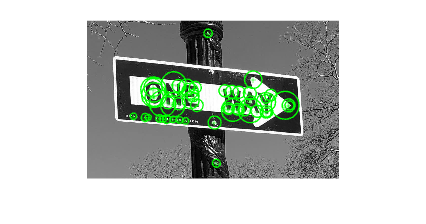


imshow(ow2)
hold on
plot(points2)

hold off
clf

### Extracting feature descriptors

Next, extract the feature descriptors and valid points. You'll need the feature descriptors to match, and the valid points to visualize the matched locations next. 

by default, `extractFeatures` uses an extraction algorithm based on the input. The exact choice of extraction algorithm is shown below:

- FREAK for a cornerPoints or BRISKPoints input object

- SURF for a SURFPoints or MSERRegions input object

- SIFT for a SIFTPoints input object

- ORB for an ORBPoints input object

- Block (a simple square neighborhood) for an *m*-by-2 input matrix of [*x y*] coordinates

[features1,validPoints1] = extractFeatures(ow1,points1);
[features2,validPoints2] = extractFeatures(ow2,points2)

### Matching features

**Default settings**

First, examine the results of matching features using `matchFeatures` with the default settings. You'll see we don't get very many matches (only 6 pairs) with these two images. 

indexPairs = matchFeatures(features1,features2)

indexPairs = 6×2 uint32 matrix
    8    3
    9   40
   10   20
   25   43
   29   36
   42    5


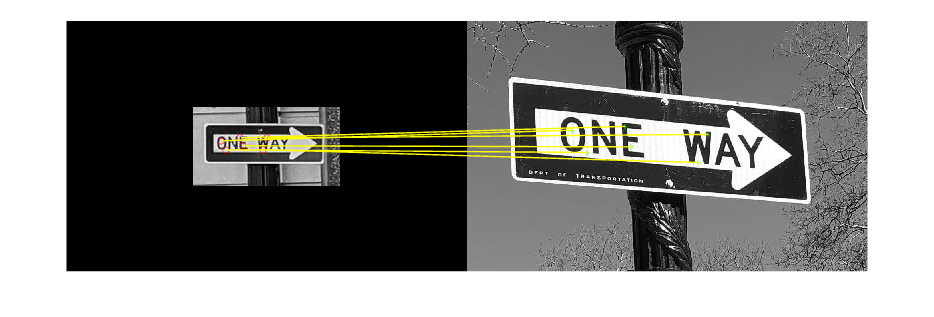


matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2)); 

showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage")

#### Match threshold settings

To increase the number of matches, you can try increasing the `"MatchThreshold"`. This allows features that are further apart in their feature space to be matched. For features like SURF, this parameter is a percent value in the range (0,100], with a default value of 1. 

indexPairs = matchFeatures(features1,features2,"MatchThreshold",1)

indexPairs = 6×2 uint32 matrix
    8    3
    9   40
   10   20
   25   43
   29   36
   42    5



matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2)); 

showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage")

#### Max ratio settings

You should have seen that even increasing the match threshold to the maximum possible value only matched 8 pairs of features. Some of the "obvious looking" features that were detected in both, such as the pointed parts on the front and sides of the arrows were still not matched. While the distance threshold may have been maximized, there was another parameter affecting the resulting matches: the `"MaxRatio"` parameter, which is a value in the range (0,1] used to reject "ambiguous matches". If a feature in one image is matched to multiple features in the other, the matches are considered ambiguous if the ratio of the distances is above the maximum set by the `"MaxRatio"` parameter. 

In the case of these one way sign images, there are a number of places where the blob shapes are very similar and therefore with the default `"MaxRatio"` of 0.6, many matches are rejected. Use the slider below to change the `"MaxRatio"` and observe the results. You should see more matches for values closer to 1. 

indexPairs = matchFeatures(features1,features2,"MatchThreshold",2,...
                                                "MaxRatio",1)

indexPairs = 19×2 uint32 matrix
    8    3
    9   40
   10   20
   15   39
   16   47
   17   32
   19   39
   20   50
   25   43
   26   36


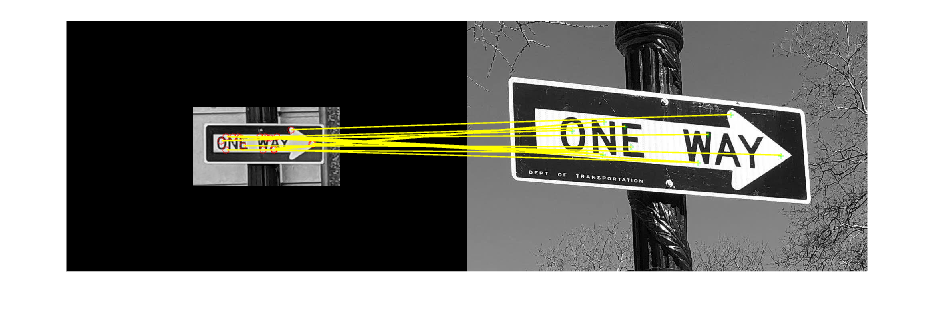


matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2)); 

showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage")

Sometimes it is easier to view one match at a time. Make sure the `"MaxRatio"` above is 1 to allow all ambiguous matches, and use the slider below to observe the results. Do you see why some of the non-unique match pairs were considered ambiguous? 

nMatches = length(matchedPoints1); 
idx = 13
showMatchedFeatures(ow1,ow2,matchedPoints1(idx),matchedPoints2(idx),"montage")

#### Unique flag 

Increasing the `"MaxRatio"` parameter to 1 increases the matches and we see that for example the pointed ends of the arrows are matched. However, it also introduced quite a few non-unique matches. To eliminate these, set the unique flag to true (the default value is false). 

indexPairs = matchFeatures(features1,features2,"MatchThreshold",2,...
                                                "MaxRatio",1,...
                                                "Unique",false)

indexPairs = 9×2 uint32 matrix
    8    3
    9   40
   10   20
   15   39
   16   47
   25   43
   29   36
   35   32
   42    5


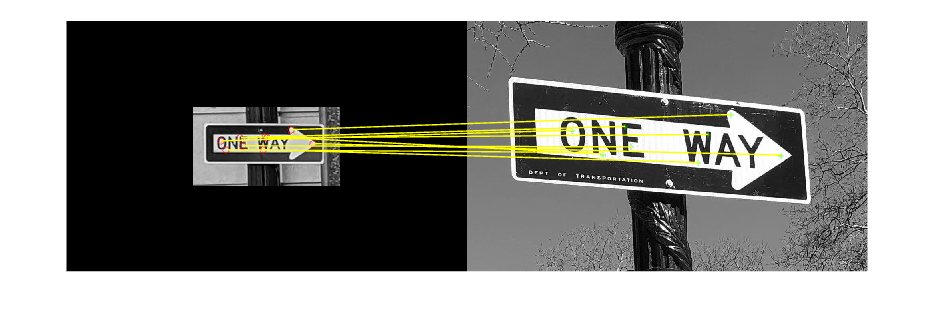


matchedPoints1 = validPoints1(indexPairs(:,1));
matchedPoints2 = validPoints2(indexPairs(:,2)); 

showMatchedFeatures(ow1,ow2,matchedPoints1,matchedPoints2,"montage");

## Stop Signs

Now that you've seen the effects some individual name-value pairs have on feature matching, explore combinations of all of them using a new pair of sign images. Use the sliders and dropdowns below to try various combinations of name-value pairs and observe the results. 

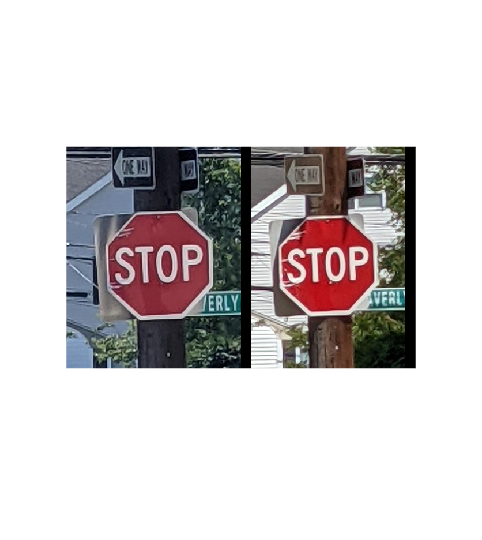

stop1RGB = imread("stop1.jpg");
stop2RGB = imread("stop2.jpg");
montage({stop1RGB,stop2RGB})

clf

Convert the RGB color images to grayscale for feature detection and extraction.

stop1 = im2gray(stop1RGB);
stop2 = im2gray(stop2RGB);

### Detect-Extract-Match (choose combined settings)

pts1 = detectSURFFeatures(stop1);
pts2 = detectSURFFeatures(stop2);

[feat1,validPts1] = extractFeatures(stop1,pts1);
[feat2,validPts2] = extractFeatures(stop2,pts2);

indexPairs = matchFeatures(feat1,feat2,"MatchThreshold",48,...
                                        "MaxRatio",0.7,...
                                        "Metric",'SAD',...
                                        "Unique",true) ;

matchedPoints1 = validPts1(indexPairs(:,1));
matchedPoints2 = validPts2(indexPairs(:,2));


Here, since the two images are nearly the same size and of the same object in different conditions, the `"blend"` option works well to visualize the matches. 

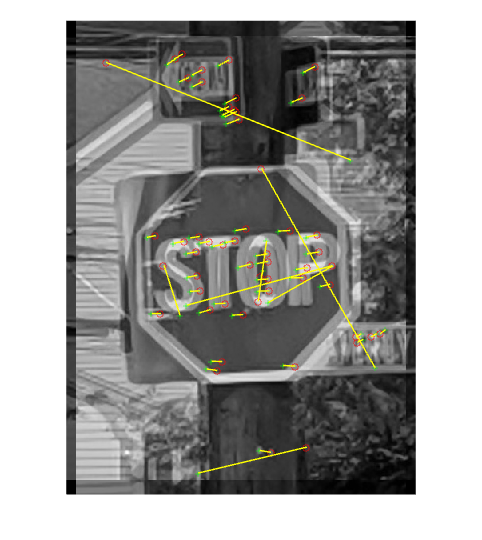

showMatchedFeatures(stop1,stop2,matchedPoints1,matchedPoints2,"blend")

comparing 3 algorithm

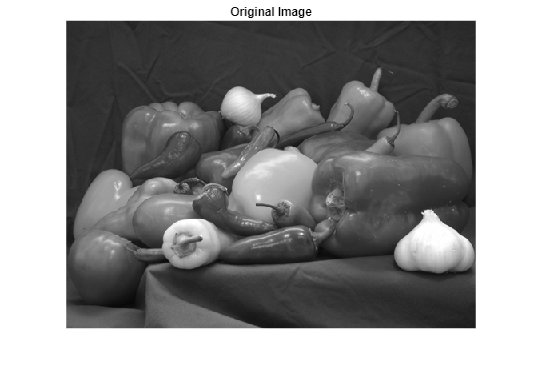

im = imread('peppers.png');
im = rgb2gray(im);

transformed = imresize(im, 2);
transformed = imrotate(transformed, 50);

figure;
imshow(im);
title('Original Image');

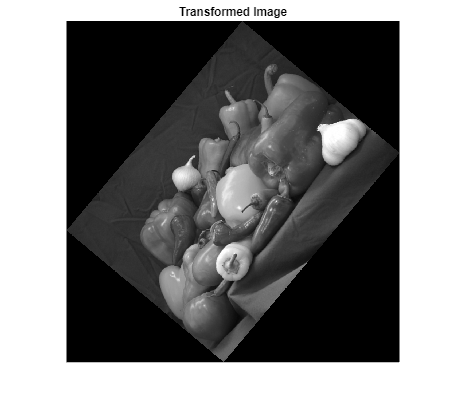


figure;
imshow(transformed);
title('Transformed Image');

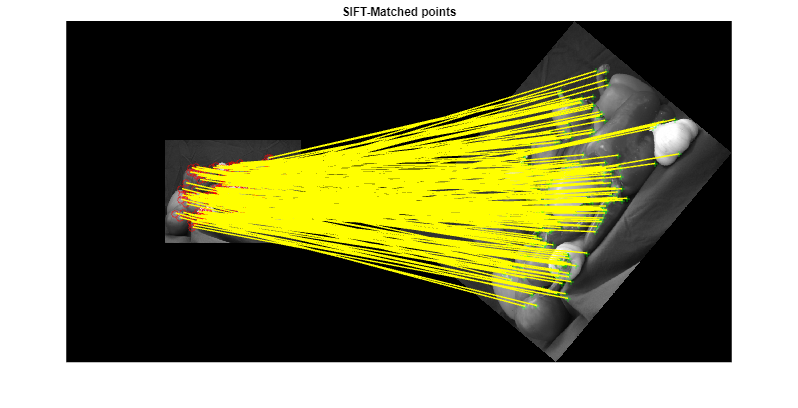


points_im = detectSIFTFeatures(im);
points_transformed = detectSIFTFeatures(transformed);
[features_im, valid_points_im] = extractFeatures(im, points_im);
[features_transformed, valid_points_transformed] = extractFeatures(transformed, points_transformed);

match_pairs_sift = matchFeatures(features_im, features_transformed);
matched_points_im = valid_points_im(match_pairs_sift(:,1));
matched_points_transformed = valid_points_transformed(match_pairs_sift(:,2));

figure;
showMatchedFeatures(im, transformed, matched_points_im, matched_points_transformed, 'montage');
title('SIFT-Matched points');

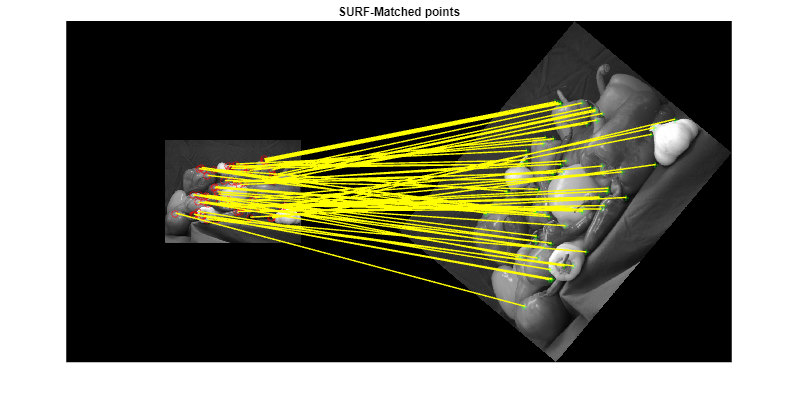


points_im = detectSURFFeatures(im);
points_transformed = detectSURFFeatures(transformed);
[features_im, valid_points_im] = extractFeatures(im, points_im);
[features_transformed, valid_points_transformed] = extractFeatures(transformed, points_transformed);

match_pairs_surf = matchFeatures(features_im, features_transformed);
matched_points_im = valid_points_im(match_pairs_surf(:,1));
matched_points_transformed = valid_points_transformed(match_pairs_surf(:,2));

figure;
showMatchedFeatures(im, transformed, matched_points_im, matched_points_transformed, 'montage');
title('SURF-Matched points');

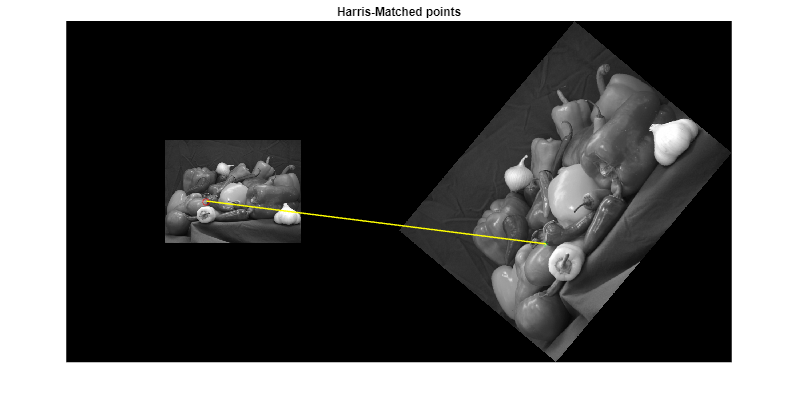


points_im = detectHarrisFeatures(im);
points_transformed = detectHarrisFeatures(transformed);
[features_im, valid_points_im] = extractFeatures(im, points_im);
[features_transformed, valid_points_transformed] = extractFeatures(transformed, points_transformed);

match_pairs_harris = matchFeatures(features_im, features_transformed);
matched_points_im = valid_points_im(match_pairs_harris(:,1));
matched_points_transformed = valid_points_transformed(match_pairs_harris(:,2));

figure;
showMatchedFeatures(im, transformed, matched_points_im, matched_points_transformed, 'montage');
title('Harris-Matched points');